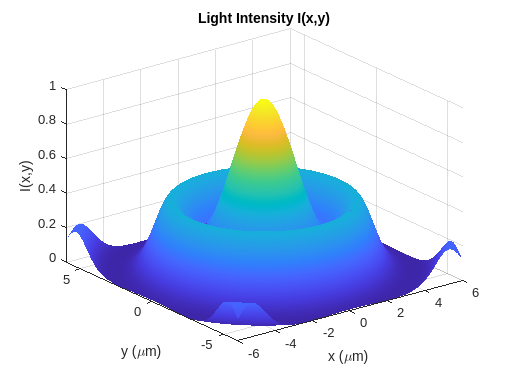

% Simulation of intensity that goes through waveguide
% based on relative alignment with the optical fiber

% Assumptions: move 0.01 um in x,y,z
% (x,y) plane is the face of the fiber/waveguide
% z is perpendicular to waveguide
% Waveguide has rectangular face, Fiber has circular face

% we are working in microns (um)

% Express the intensity of light as a function of (x, y)
% Render a 2D surface
% Also put the second mode to just to try

% I(x, y) = exp[-4(x^2 + y^2)] + 0.25exp{-6[(x^2+y^2)^(1/2)-1.5]^2}

% plot light intensity as a function of position
% from center of the fiber
N = 6.0;
x=linspace(-N, N);
y=x;

[X,Y] = meshgrid(x,y);
Z = I(X, Y);
surf(X,Y,Z, 'FaceColor', 'interp', 'EdgeColor', 'none')
title("Light Intensity I(x,y)");
xlabel("x ({\mu}m)");
ylabel("y ({\mu}m)");
zlabel("I(x,y)");

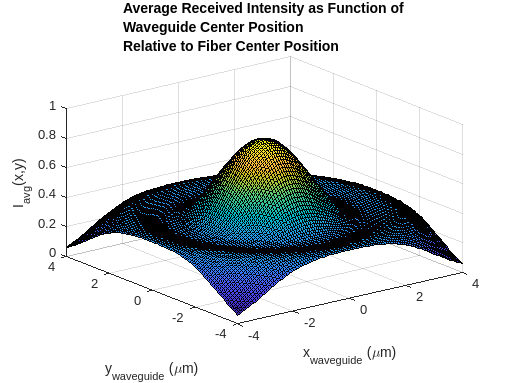


Nw = 4.0;
% generate some possible waveguide positions relative to the fiber
[Xw, Yw] = meshgrid(linspace(-Nw,Nw), ...
                    linspace(-Nw,Nw));

% lengths of sides of waveguide opening len, wid (assume rectangular)
waveguide_param.wid = 2.0;
waveguide_param.len = 2.0;
% |*********|
% |    .    | len x
% |         |
% ***********
%    wid y

% Initialize a matrix to store average intensity values
avg_intensity = zeros(size(Xw));

% Calculate the average intensity for each waveguide position
for i = 1:size(Xw, 1)
    for j = 1:size(Yw, 2)
        x_center = Xw(i, j);
        y_center = Yw(i, j);
        
        [X_aligned, Y_aligned] = overlap(x_center, y_center, waveguide_param);

        % Calculate the average intensity for the current waveguide position
        avg_intensity(i, j) = avg(@I, X_aligned, Y_aligned);
    end
end

% plot avg received intensity as a function of relative alignment
% between the fiber and the waveguide
surf(Xw,Yw, avg_intensity);
title("Average Received Intensity as Function of\newlineWaveguide Center Position\newlineRelative to Fiber Center Position","HorizontalAlignment","center")
xlabel("x_{waveguide} ({\mu}m)")
ylabel("y_{waveguide} ({\mu}m)")
zlabel("I_{avg}(x,y)")

function intensity = I(x, y)
intensity = exp(-0.25.*(x.^2 + y.^2)) + ...
            0.4*exp(-1.*((x.^2+y.^2).^(1/2)-2*2).^2) + ...
            0.2*exp(-2.*((x.^2+y.^2).^(1/2)-2*4).^2);
end

function [X_aligned, Y_aligned] = overlap(wx, wy, waveguide_param)
num_points = 100;
[X_aligned, Y_aligned] = meshgrid(linspace(wx-waveguide_param.wid/2,wx+waveguide_param.wid/2, num_points), ...
                                  linspace(wy-waveguide_param.len/2,wy+waveguide_param.len/2, num_points));
end

% average value of f(x,y) over given domain X,Y
function fun_avg = avg(f,X,Y)
intensity_values = f(X, Y);
fun_avg = mean(intensity_values(:));
end

% output intensity pattern with more modes
function intensity = I_N(x,y,N)
intensity = exp(-2.*(x.^2 + y.^2));
if N > 1
    for n = 2:N
        intensity = intensity + (0.5)^(n-1)*exp(-(2)^n*(sqrt(x.^2+y.^2)-1.5*(2)^(n-1))^(2*(n-1)));
    end
end
end